clear
clc

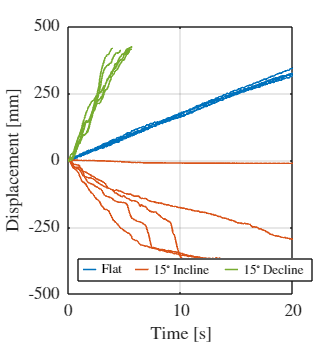

directory = 'data/saw/without_skin/flat';
files = dir([directory '\*.txt']);

for i=1:length(files)
    file = [files(i).folder '\' files(i).name];
    data = importdata(file);

    t_flat(:,i) = data.data(:,1);
    x_flat(:,i) = data.data(:,2);
    y_flat(:,i) = data.data(:,3);
end

directory = 'data/saw/without_skin/incline';
files = dir([directory '\*.txt']);

for i=1:length(files)
    file = [files(i).folder '\' files(i).name];
    data = importdata(file);

    t_incline(:,i) = data.data(:,1);
    x_incline(:,i) = data.data(:,2);
    y_incline(:,i) = data.data(:,3);
end

directory = 'data/saw/without_skin/decline';
files = dir([directory '\*.txt']);

for i=1:length(files)
    file = [files(i).folder '\' files(i).name];
    data = importdata(file);

    t_decline(1:length(data.data(:,1)),i) = data.data(:,1);
    x_decline(1:length(data.data(:,1)),i) = data.data(:,2);
    y_decline(1:length(data.data(:,1)),i) = data.data(:,3);
end

fig = figure();
hold on
x0=10;
y0=10;
w=7.5;
h=8;
set(gcf,'units','centimeter','position',[x0,y0,w,h]);
plot(t_flat,x_flat,'Color',"#0072BD",'LineWidth',1)
plot(t_incline,x_incline,'Color',"#D95319",'LineWidth',1)
plot(t_decline(:,1),x_decline(:,1),t_decline(1:101,2),x_decline(1:101,2),t_decline(1:143,3),x_decline(1:143,3),t_decline(1:118,4),x_decline(1:118,4),t_decline(1:138,5),x_decline(1:138,5),'Color',"#77AC30",'LineWidth',1)
lgnd = legend('Flat','','','','','$15^{\circ}$ Incline','','','','','$15^{\circ}$ Decline','Interpreter','latex','location','southwest','Orientation','horizontal');
lgnd.ItemTokenSize(1) = 8;
fontsize(10,'points')
fontsize(lgnd,8,'points')
yticks([-500:250:500])
ylabel("Displacement [mm]","Interpreter","latex")
xlabel('Time [s]','interpreter','latex')
set(gca,'TickLabelInterpreter','latex')
grid on
box on
hold off


dxdt_flat = diff(x_flat) ./ diff(t_flat);
v_avg = mean(dxdt_flat,'omitnan');
v_mean(1,1) = mean(v_avg)

v_mean = 16.2546

v_std(1,1) = std(v_avg)

v_std = 0.5373

v_s(1,1) = std(v_avg)/sqrt(length(v_avg))

v_s = 0.2403

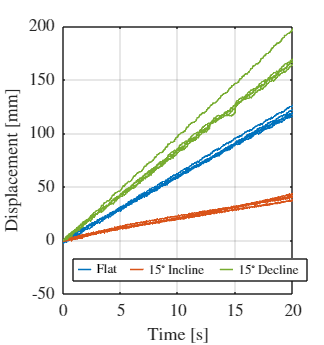

directory = 'data/saw/with_skin/flat';
files = dir([directory '\*.txt']);

for i=1:length(files)
    file = [files(i).folder '\' files(i).name];
    data = importdata(file);

    t_flat(:,i) = data.data(:,1);
    x_flat(:,i) = data.data(:,2);
    y_flat(:,i) = data.data(:,3);
end

directory = 'data/saw/with_skin/incline';
files = dir([directory '\*.txt']);

for i=1:length(files)
    file = [files(i).folder '\' files(i).name];
    data = importdata(file);

    t_incline(:,i) = data.data(:,1);
    x_incline(:,i) = data.data(:,2);
    y_incline(:,i) = data.data(:,3);
end

directory = 'data/saw/with_skin/decline';
files = dir([directory '\*.txt']);

for i=1:length(files)
    file = [files(i).folder '\' files(i).name];
    data = importdata(file);

    t_decline(1:length(data.data(:,1)),i) = data.data(:,1);
    x_decline(1:length(data.data(:,1)),i) = data.data(:,2);
    y_decline(1:length(data.data(:,1)),i) = data.data(:,3);
end

fig = figure();
hold on
x0=10;
y0=10;
w=7.5;
h=8;
set(gcf,'units','centimeter','position',[x0,y0,w,h]);
plot(t_flat,x_flat,'Color',"#0072BD",'LineWidth',1)
plot(t_incline,x_incline,'Color',"#D95319",'LineWidth',1)
plot(t_decline,x_decline,'Color',"#77AC30",'LineWidth',1)
lgnd = legend('Flat','','','','','$15^{\circ}$ Incline','','','','','$15^{\circ}$ Decline','Interpreter','latex','location','southwest','Orientation','horizontal');
lgnd.ItemTokenSize(1) = 8;
fontsize(10,'points')
fontsize(lgnd,8,'points')
%yticks([-500:250:500])
%ylim([-500 500])
ylabel("Displacement [mm]","Interpreter","latex")
xlabel('Time [s]','interpreter','latex')
set(gca,'TickLabelInterpreter','latex')
grid on
box on
hold off


dxdt_flat = diff(x_flat) ./ diff(t_flat);
v_avg = mean(dxdt_flat,'omitnan');
v_mean(1,2) = mean(v_avg)

v_mean =    16.2546    6.0188
    7.2740         0
    2.3099         0


v_std(1,2) = std(v_avg)

v_std =     0.5373    0.1857
    0.0927         0
    0.0939         0


v_s(1,2) = std(v_avg)/sqrt(length(v_avg))

v_s =     0.2403    0.0831
         0    0.0557
         0    0.3103



dxdt_incline = diff(x_incline) ./ diff(t_incline);
v_avg = mean(dxdt_incline,'omitnan');
v_mean(2,2) = mean(v_avg)

v_mean =    16.2546    6.0188
    7.2740    2.0074
    2.3099         0


v_std(2,2) = std(v_avg)

v_std =     0.5373    0.1857
    0.0927    0.1246
    0.0939         0


v_s(2,2) = std(v_avg)/sqrt(length(v_avg))

v_s =     0.2403    0.0831
         0    0.0557
         0    0.3103



dxdt_decline = diff(x_decline) ./ diff(t_decline);
v_avg = mean(dxdt_decline,'omitnan');
v_mean(3,2) = mean(v_avg)

v_mean =    16.2546    6.0188
    7.2740    2.0074
    2.3099    8.6600


v_std(3,2) = std(v_avg)

v_std =     0.5373    0.1857
    0.0927    0.1246
    0.0939    0.6939


v_s(3,2) = std(v_avg)/sqrt(length(v_avg))

v_s =     0.2403    0.0831
         0    0.0557
         0    0.3103


b = figure;
figure(b);
hold on
bar(v_mean);
set(gca, 'XTickLabel', {'Flat' 'Incline' 'Decline'});
set(gca,'XTick',[1 2 3])
%set(gca,'YTick',[0 5 10 15])
ylim([0 17])
ylabel('Velocity [mm s$^{-1}$]','Interpreter','latex')

ngroups = size(v_mean, 1);
nbars = size(v_mean, 2);
% Calculating the width for each bar group
groupwidth = min(0.8, nbars/(nbars + 1.5));
for i = 1:nbars
    x = (1:ngroups) - groupwidth/2 + (2*i-1) * groupwidth / (2*nbars);
    er = errorbar(x, v_mean(:,i), v_std(:,i));
    er.Color = [0 0 0];
    er.LineStyle = 'none';
end
x0=10;
y0=10;
w=4.3;
h=8.03;
set(gcf,'units','centimeter','position',[x0,y0,w,h]);
lgnd = legend('Without skin', '1.5 mm skin','Interpreter','latex')

lgnd =   Legend (Without skin, 1.5 mm skin) with properties:

         String: {'Without skin'  '1.5 mm skin'}
       Location: 'northeast'
    Orientation: 'vertical'
       FontSize: 7.2000
       Position: [0.2180 0.8006 0.6527 0.0906]
          Units: 'normalized'

  Show all properties


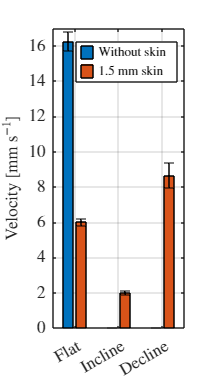

lgnd.ItemTokenSize(1) =7;
fontsize(10,'points')
fontsize(lgnd,8,'points')
set(gca,'TickLabelInterpreter','latex')
grid on
box on
hold off

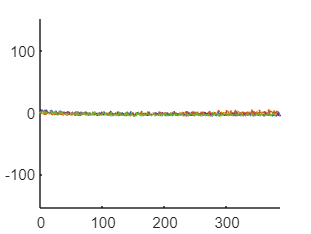

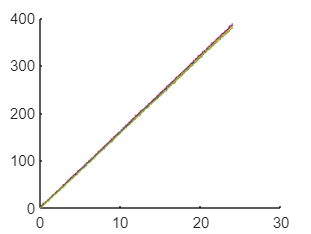

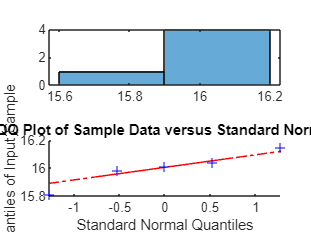

v_plywood = 15.9997

std_plywood = 0.1240

se_plywood = 0.0555

s_plywood = struct with fields:
    v_avg: [16.0417 16.0136 15.9854 16.1499 15.8079]


directory = 'data/three-surface-locomotion/plywood/no-cycle';
[v_plywood, std_plywood, se_plywood, s_plywood] = forward_analysis(directory)

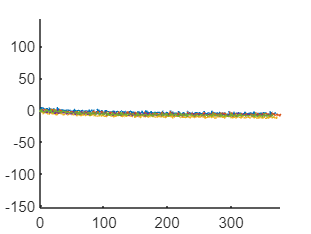

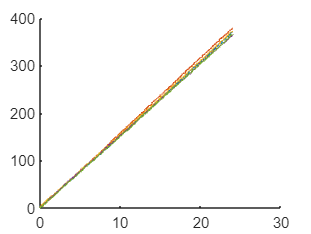

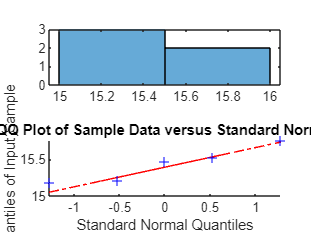

v_plywood_05 = 15.4298

std_plywood_05 = 0.2382

se_plywood_05 = 0.1065

s_plywood_05 = struct with fields:
    v_avg: [15.4740 15.7591 15.5211 15.2056 15.1891]



directory = 'data/three-surface-locomotion/plywood/05Hz';
[v_plywood_05, std_plywood_05, se_plywood_05, s_plywood_05] = forward_analysis(directory)

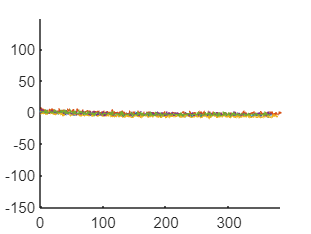

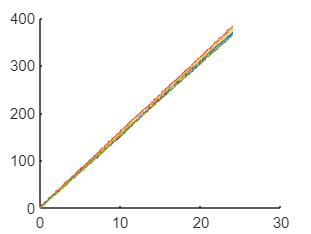

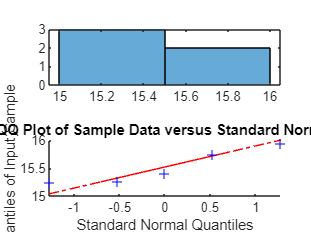

v_plywood_09 = 15.5159

std_plywood_09 = 0.3111

se_plywood_09 = 0.1391

s_plywood_09 = struct with fields:
    v_avg: [15.4056 15.9418 15.7376 15.2554 15.2392]



directory = 'data/three-surface-locomotion/plywood/09Hz';
[v_plywood_09, std_plywood_09, se_plywood_09, s_plywood_09] = forward_analysis(directory)

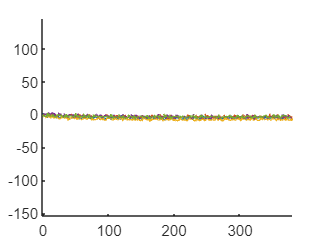

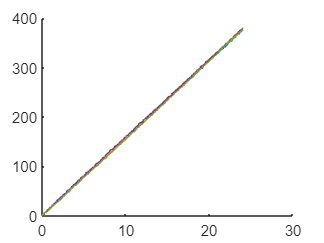

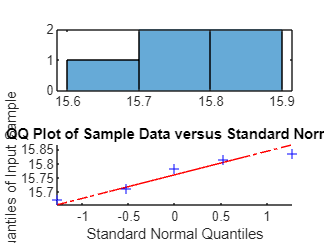

directory = 'data/three-surface-locomotion/pmma/no-cycle';
[v_pmma, std_pmma, se_pmma, s_pmma] = forward_analysis(directory);

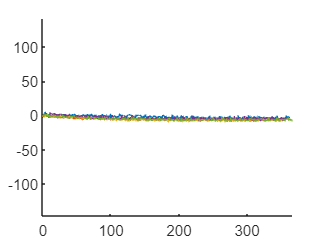

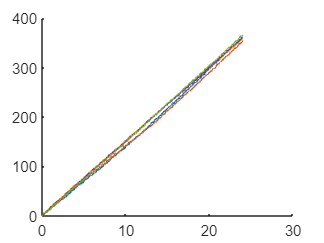

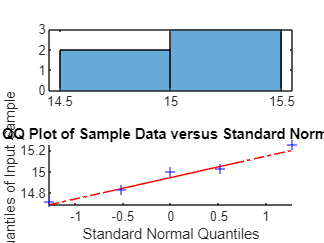


directory = 'data/three-surface-locomotion/pmma/05Hz';
[v_pmma_05, std_pmma_05, se_pmma_05, s_pmma_05] = forward_analysis(directory);

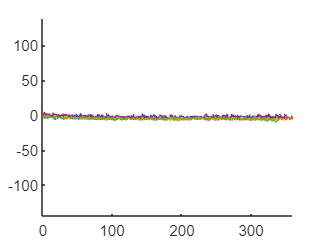

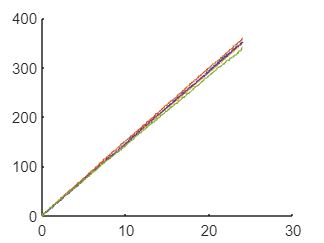

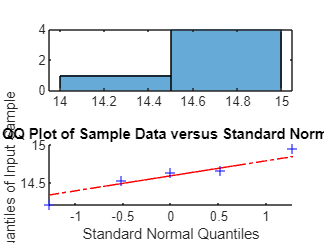


directory = 'data/three-surface-locomotion/pmma/09Hz';
[v_pmma_09, std_pmma_09, se_pmma_09, s_pmma_09] = forward_analysis(directory);

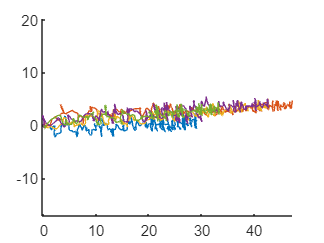

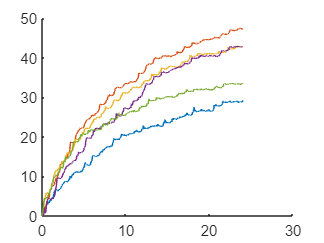

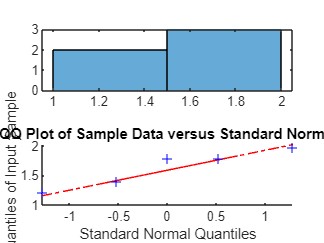

v_sand = 1.6273

std_sand = 0.3133

se_sand = 0.1401

s_sand = struct with fields:
    v_avg: [1.2137 1.9702 1.7811 1.7819 1.3896]


directory = 'data/three-surface-locomotion/sand/no-cycle';
[v_sand, std_sand, se_sand, s_sand] = forward_analysis(directory)

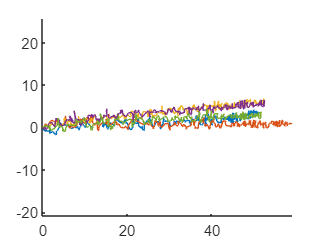

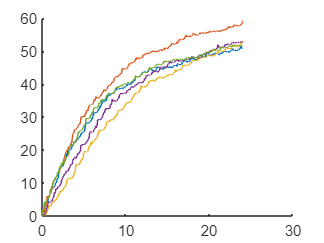

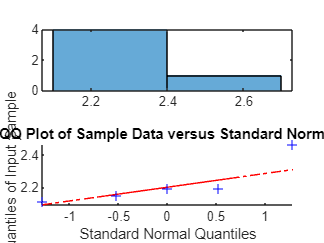

v_sand_05 = 2.2232

std_sand_05 = 0.1367

se_sand_05 = 0.0612

s_sand_05 = struct with fields:
    v_avg: [2.1158 2.4605 2.1948 2.1941 2.1505]



directory = 'data/three-surface-locomotion/sand/05Hz';
[v_sand_05, std_sand_05, se_sand_05, s_sand_05] = forward_analysis(directory)

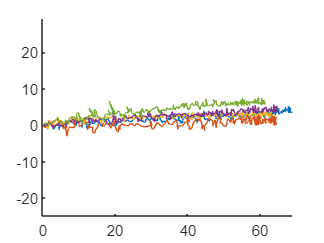

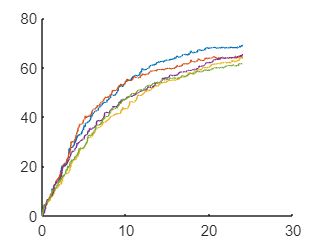

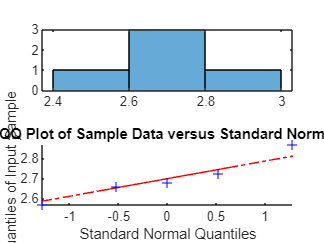

v_sand_09 = 2.6988

std_sand_09 = 0.1113

se_sand_09 = 0.0498

s_sand_09 = struct with fields:
    v_avg: [2.8691 2.6763 2.6575 2.7252 2.5661]



directory = 'data/three-surface-locomotion/sand/09Hz';
[v_sand_09, std_sand_09, se_sand_09, s_sand_09] = forward_analysis(directory)

v_mean = [v_plywood v_plywood_05 v_plywood_09;
          v_pmma v_pmma_05 v_pmma_09
          v_sand v_sand_05 v_sand_09];
v_std = [std_plywood std_plywood_05 std_plywood_09;
         std_pmma std_pmma_05 std_pmma_09
         std_sand std_sand_05 std_sand_09];

b = figure;
figure(b);
hold on
bh = bar(v_mean);
bh(3).FaceColor = [0.4660 0.6740 0.1880];
set(gca, 'XTickLabel', {'Plywood' 'PMMA' 'Sand'});
set(gca,'XTick',[1 2 3])
ylabel('Velocity [mm s$^{-1}$]','Interpreter','latex')

ngroups = size(v_mean, 1);
nbars = size(v_mean, 2);
% Calculating the width for each bar group
groupwidth = min(0.8, nbars/(nbars + 1.5));
for i = 1:nbars
    x = (1:ngroups) - groupwidth/2 + (2*i-1) * groupwidth / (2*nbars);
    er = errorbar(x, v_mean(:,i), v_std(:,i));
    er.Color = [0 0 0];
    er.LineStyle = 'none';
end
x0=10;
y0=10;
w=6.3;
h=5.85;
ylim([0 23])
set(gcf,'unit','centimeter','position',[x0,y0,w,h]);
lgnd = legend('No cycle', '0.5 Hz cycle', '0.9 Hz cycle','interpreter','latex')

lgnd =   Legend (No cycle, 0.5 Hz cycle, 0.9 Hz cycle) with properties:

         String: {'No cycle'  '0.5 Hz cycle'  '0.9 Hz cycle'}
       Location: 'northeast'
    Orientation: 'vertical'
       FontSize: 8.1000
       Position: [0.4216 0.6873 0.4530 0.1980]
          Units: 'normalized'

  Show all properties


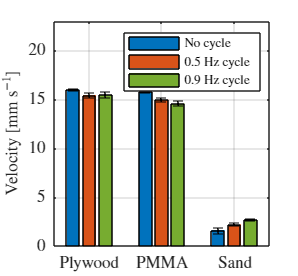

fontsize(10,'points')
fontsize(lgnd,8,'points')
set(gca,'TickLabelInterpreter','latex')
grid on
box on
hold off

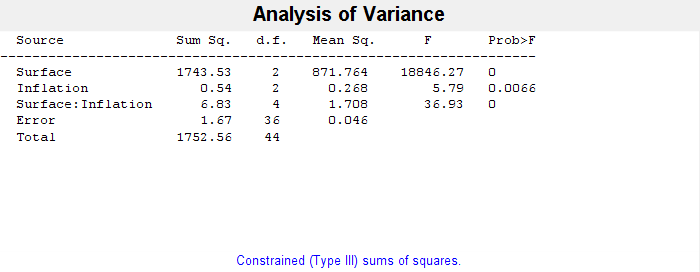

v = [s_plywood.v_avg'
    s_plywood_05.v_avg'
    s_plywood_09.v_avg'
    s_pmma.v_avg'
    s_pmma_05.v_avg'
    s_pmma_09.v_avg'
    s_sand.v_avg'
    s_sand_05.v_avg'
    s_sand_09.v_avg'];
surfaces   = {"plywood", "pmma", "sand"};
inflations = {"0Hz", "0.5Hz", "09Hz"};
surface = strings(45,1);
inflation = strings(45,1);
idx = 1;
for s = 1:3
    for i = 1:3
        for rep = 1:5
            surface(idx) = surfaces(s);
            inflation(idx) = inflations(i);
            idx = idx + 1;
        end
    end
end

surface = categorical(surface);
inflation = categorical(inflation);

[p, tbl, stats] = anovan(v, {surface, inflation}, ...
                         'model', 'interaction', ...
                         'varnames', {'Surface', 'Inflation'});

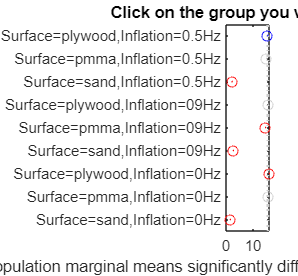

[c, m, h, gnames] = multcompare(stats, 'Dimension', [1 2], 'CriticalValueType','bonferroni');  % Interaction (if significant)

for k = 1:length(c(:,6))
    g1 = gnames{c(k,1)};
    g2 = gnames{c(k,2)};
    fprintf('%s differs from %s (p = %.3f)\n', g1, g2, c(k,6));
end

Surface=plywood,Inflation=0.5Hz differs from Surface=pmma,Inflation=0.5Hz (p = 0.059)
Surface=plywood,Inflation=0.5Hz differs from Surface=sand,Inflation=0.5Hz (p = 0.000)
Surface=plywood,Inflation=0.5Hz differs from Surface=plywood,Inflation=09Hz (p = 1.000)
Surface=plywood,Inflation=0.5Hz differs from Surface=pmma,Inflation=09Hz (p = 0.000)
Surface=plywood,Inflation=0.5Hz differs from Surface=sand,Inflation=09Hz (p = 0.000)
Surface=plywood,Inflation=0.5Hz differs from Surface=plywood,Inflation=0Hz (p = 0.006)
Surface=plywood,Inflation=0.5Hz differs from Surface=pmma,Inflation=0Hz (p = 0.689)
Surface=plywood,Inflation=0.5Hz differs from Surface=sand,Inflation=0Hz (p = 0.000)
Surface=pmma,Inflation=0.5Hz differs from Surface=sand,Inflation=0.5Hz (p = 0.000)
Surface=pmma,Inflation=0.5Hz differs from Surface=plywood,Inflation=09Hz (p = 0.010)
Surface=pmma,Inflation=0.5Hz differs from Surface=pmma,Inflation=09Hz (p = 0.377)
Surface=pmma,Inflation=0.5Hz differs from Surface=sand,Inflation=

directory = 'data/three-surface-locomotion/plywood/no-cycle';
files = dir([directory '\*.txt']);

for i=1:length(files)
    file = [files(i).folder '\' files(i).name];
    data = importdata(file);

    t(:,i) = data.data(:,1);
    x_plywood_no(:,i) = data.data(:,2);
    y_plywood_no(:,i) = data.data(:,3);
end

directory = 'data/three-surface-locomotion/plywood/05Hz';
files = dir([directory '\*.txt']);

for i=1:length(files)
    file = [files(i).folder '\' files(i).name];
    data = importdata(file);

    t(:,i) = data.data(:,1);
    x_plywood_05Hz(:,i) = data.data(:,2);
    y_plywood_05Hz(:,i) = data.data(:,3);
end

directory = 'data/three-surface-locomotion/plywood/09Hz';
files = dir([directory '\*.txt']);

for i=1:length(files)
    file = [files(i).folder '\' files(i).name];
    data = importdata(file);

    t(:,i) = data.data(:,1);
    x_plywood_09Hz(:,i) = data.data(:,2);
    y_plywood_09Hz(:,i) = data.data(:,3);
end

fig = figure();
hold on
plot(t(:,1),mean(sqrt(x_plywood_no.^2+y_plywood_no.^2)'),'Color',"#0072BD",'LineWidth',1)
plot(t(:,1),mean(sqrt(x_plywood_05Hz.^2+y_plywood_05Hz.^2)'),'Color',"#D95319",'LineWidth',1)
plot(t(:,1),mean(sqrt(x_plywood_09Hz.^2+y_plywood_09Hz.^2)'),'Color',"#77AC30",'LineWidth',1)
x0=10;
y0=10;
w=6.3;
h=6.3;
set(gcf,'unit','centimeters','position',[x0,y0,w,h]);
lgnd = legend('No cycle', '0.5 Hz Cycle', '0.9 Hz Cycle','Location','northwest','Interpreter','latex');

lgnd =   Legend (No cycle, 0.5 Hz Cycle, 0.9 Hz Cycle) with properties:

         String: {'No cycle'  '0.5 Hz Cycle'  '0.9 Hz Cycle'}
       Location: 'northwest'
    Orientation: 'vertical'
       FontSize: 8.1000
       Position: [0.1623 0.7040 0.4656 0.1841]
          Units: 'normalized'

  Show all properties


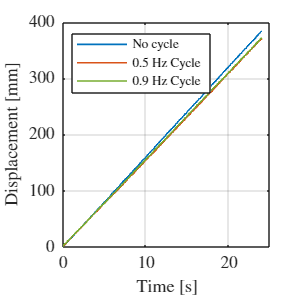

fontsize(10,'points')
fontsize(lgnd,8,'points')
ylabel("Displacement [mm]","Interpreter","latex")
xlabel('Time [s]','interpreter','latex')
set(gca,'TickLabelInterpreter','latex')
xlim([0 25])
grid on
box on
hold off

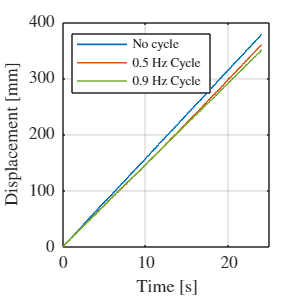

directory = 'data/three-surface-locomotion/pmma/no-cycle';
files = dir([directory '\*.txt']);

for i=1:length(files)
    file = [files(i).folder '\' files(i).name];
    data = importdata(file);

    t(:,i) = data.data(:,1);
    x_pmma_no(:,i) = data.data(:,2);
    y_pmma_no(:,i) = data.data(:,3);
end

directory = 'data/three-surface-locomotion/pmma/05Hz';
files = dir([directory '\*.txt']);

for i=1:length(files)
    file = [files(i).folder '\' files(i).name];
    data = importdata(file);

    t(:,i) = data.data(:,1);
    x_pmma_05Hz(:,i) = data.data(:,2);
    y_pmma_05Hz(:,i) = data.data(:,3);
end

directory = 'data/three-surface-locomotion/pmma/09Hz';
files = dir([directory '\*.txt']);

for i=1:length(files)
    file = [files(i).folder '\' files(i).name];
    data = importdata(file);

    t(:,i) = data.data(:,1);
    x_pmma_09Hz(:,i) = data.data(:,2);
    y_pmma_09Hz(:,i) = data.data(:,3);
end

fig = figure();
hold on
plot(t(:,1),mean(sqrt(x_pmma_no.^2+y_pmma_no.^2)'),'Color',"#0072BD",'LineWidth',1)
plot(t(:,1),mean(sqrt(x_pmma_05Hz.^2+y_pmma_05Hz.^2)'),'Color',"#D95319",'LineWidth',1)
plot(t(:,1),mean(sqrt(x_pmma_09Hz.^2+y_pmma_09Hz.^2)'),'Color',"#77AC30",'LineWidth',1)
x0=10;
y0=10;
w=6.3;
h=6.3;
set(gcf,'unit','centimeter','position',[x0,y0,w,h]);
lgnd = legend('No cycle', '0.5 Hz Cycle', '0.9 Hz Cycle','Location','northwest','Interpreter','latex');
fontsize(10,'points')
fontsize(lgnd,8,'points')
ylabel("Displacement [mm]","Interpreter","latex")
xlabel('Time [s]','interpreter','latex')
set(gca,'TickLabelInterpreter','latex')
xlim([0 25])
grid on
box on
hold off

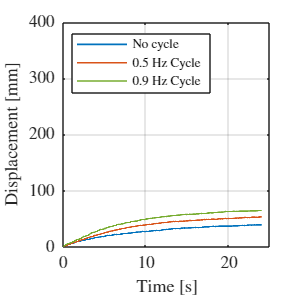

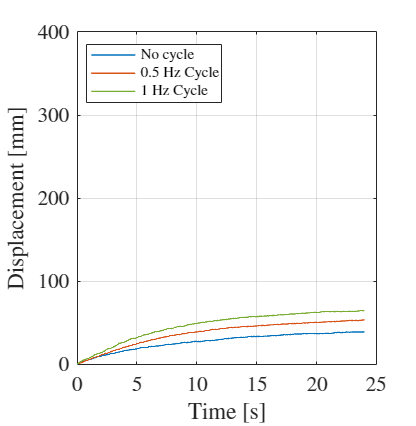

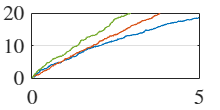

directory = 'data/three-surface-locomotion/sand/no-cycle';
files = dir([directory '\*.txt']);

for i=1:length(files)
    file = [files(i).folder '\' files(i).name];
    data = importdata(file);

    t(:,i) = data.data(:,1);
    x_sand_no(:,i) = data.data(:,2);
    y_sand_no(:,i) = data.data(:,3);
end

directory = 'data/three-surface-locomotion/sand/05Hz';
files = dir([directory '\*.txt']);

for i=1:length(files)
    file = [files(i).folder '\' files(i).name];
    data = importdata(file);

    t(:,i) = data.data(:,1);
    x_sand_05Hz(:,i) = data.data(:,2);
    y_sand_05Hz(:,i) = data.data(:,3);
end

directory = 'data/three-surface-locomotion/sand/09Hz';
files = dir([directory '\*.txt']);

for i=1:length(files)
    file = [files(i).folder '\' files(i).name];
    data = importdata(file);

    t(:,i) = data.data(:,1);
    x_sand_09Hz(:,i) = data.data(:,2);
    y_sand_09Hz(:,i) = data.data(:,3);
end

fig = figure();
hold on
plot(t(:,1),mean(sqrt(x_sand_no.^2+y_sand_no.^2)'),'Color',"#0072BD",'LineWidth',1)
plot(t(:,1),mean(sqrt(x_sand_05Hz.^2+y_sand_05Hz.^2)'),'Color',"#D95319",'LineWidth',1)
plot(t(:,1),mean(sqrt(x_sand_09Hz.^2+y_sand_09Hz.^2)'),'Color',"#77AC30",'LineWidth',1)
x0=10;
y0=10;
w=6.3;
h=6.3;
set(gcf,'unit','centimeter','position',[x0,y0,w,h]);
lgnd = legend('No cycle', '0.5 Hz Cycle', '0.9 Hz Cycle','Location','northwest','Interpreter','latex');
fontsize(10,'points')
fontsize(lgnd,8,'points')
ylabel("Displacement [mm]","Interpreter","latex")
xlabel('Time [s]','interpreter','latex')
ylim([0 400])
xlim([0 25])
set(gca,'TickLabelInterpreter','latex')
grid on
box on
hold off

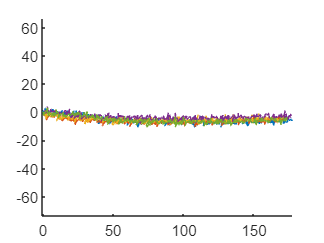

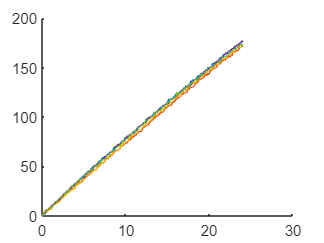

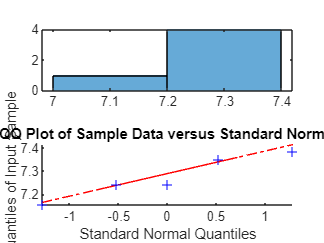

directory = 'data/inclination/incline-15-degree';
[v_15, std_15, se_15, s_15] = forward_analysis(directory);

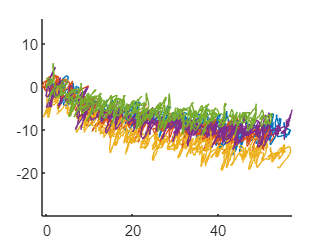

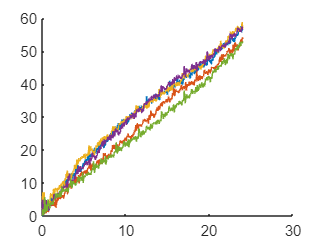

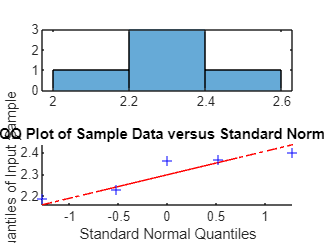


directory = 'data/inclination/incline-25-degree';
[v_25, std_25, se_25, s_25] = forward_analysis(directory);


v_mean = [v_plywood
          v_15
          v_25];
v_std = [std_plywood
         std_15
         std_25];

b = figure;
figure(b);
hold on
bh = bar(v_mean);
%bh(3).FaceColor = [0.4660 0.6740 0.1880];
set(gca, 'XTickLabel', {'Flat' '15$^{\circ}$ Incline' '25$^{\circ}$ Incline'});
set(gca,'TickLabelInterpreter','latex')
set(gca,'XTick',[1 2 3])
ylabel('Velocity [mm s$^{-1}$]','Interpreter','latex')

ngroups = size(v_mean, 1);
nbars = size(v_mean, 2);
% Calculating the width for each bar group
groupwidth = min(0.8, nbars/(nbars + 1.5));
for i = 1:nbars
    x = (1:ngroups) - groupwidth/2 + (2*i-1) * groupwidth / (2*nbars);
    er = errorbar(x, v_mean(:,i), v_std(:,i));
    er.Color = [0 0 0];
    er.LineStyle = 'none';
end
x0=10;
y0=10;
w=6.3;
h=5.85;
ylim([0 23])
set(gcf,'unit','centimeter','position',[x0,y0,w,h]);
%lgnd = legend('No cycle', '0.5 Hz cycle', '0.9 Hz cycle','interpreter','latex')
fontsize(10,'points')
fontsize(lgnd,8,'points')

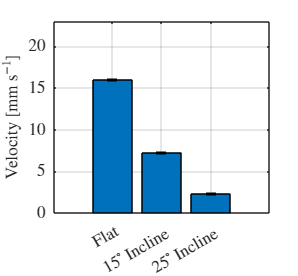

grid on
box on
hold off

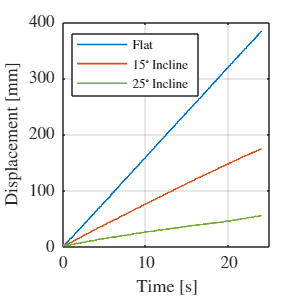

directory = 'data/inclination/incline-15-degree';
files = dir([directory '\*.txt']);

for i=1:length(files)
    file = [files(i).folder '\' files(i).name];
    data = importdata(file);

    t(:,i) = data.data(:,1);
    x_plywood_15(:,i) = data.data(:,2);
    y_plywood_15(:,i) = data.data(:,3);
end

directory = 'data/inclination/incline-25-degree';
files = dir([directory '\*.txt']);

for i=1:length(files)
    file = [files(i).folder '\' files(i).name];
    data = importdata(file);

    t(:,i) = data.data(:,1);
    x_plywood_25(:,i) = data.data(:,2);
    y_plywood_25(:,i) = data.data(:,3);
end

fig = figure();
hold on
plot(t(:,1),mean(sqrt(x_plywood_no.^2+y_plywood_no.^2)'),'Color',"#0072BD",'LineWidth',1)
plot(t(:,1),mean(sqrt(x_plywood_15.^2+y_plywood_15.^2)'),'Color',"#D95319",'LineWidth',1)
plot(t(:,1),mean(sqrt(x_plywood_25.^2+y_plywood_25.^2)'),'Color',"#77AC30",'LineWidth',1)
x0=10;
y0=10;
w=6.3;
h=6.3;
set(gcf,'unit','centimeter','position',[x0,y0,w,h]);
lgnd = legend('Flat', '15$^{\circ}$ Incline', '25$^{\circ}$ Incline','Location','northwest','Interpreter','latex');
fontsize(10,'points')
fontsize(lgnd,8,'points')
ylabel("Displacement [mm]","Interpreter","latex")
xlabel('Time [s]','interpreter','latex')
ylim([0 400])
xlim([0 25])
set(gca,'TickLabelInterpreter','latex')
grid on
box on
hold off